- to check if the code is working.

- Calculations

clc; clear; close all;
list = {'Check Code','Obtaining solution'} ;
[indx,tf] = listdlg('ListString',list,"SelectionMode","single");
while tf==0
[indx,tf] = listdlg('ListString',list,"SelectionMode","single");
end
if indx==1
    list1 = {'Linear',...
                           'Quadratic '};
[indx1,tf1] = listdlg('ListString',list1);
while tf1==0
[indx1,tf1] = listdlg('ListString',list1);
end
    if indx1==1
        prompt   = {'a in ax+b #, b in ax+b #, lower limit, upper limit'};
        name     = 'Input';
        numlines = 4;
        dlg_ans  = inputdlg(prompt, name, numlines);
        a11=str2num(dlg_ans{1}(1,:));
        b11=str2num(dlg_ans{1}(2,:));
        llim=str2num(dlg_ans{1}(3,:));
        ulim=str2num(dlg_ans{1}(4,:));
        [x,y]=lform(a11,b11,0,llim,ulim);
        [a,b]=leastsquarem1(x,y);
        hold on
        x1=min(x):max(x);
        y1=a*x1+b;
        plot(x1,y1,'k--')
        ylabel("no of trades")
        xlabel("closing value")
        title("no. of trades vs closing value")
        err1=error1(x,y,a,b,0,1);
    err1,a,b
    elseif indx1==2
        prompt   = {'a in ax2+bx+c #, b in ax2+bx+c #, c in  ax2+bx+c, lower limit, upper limit'};
        name     = 'Input';
        numlines = 5;
        dlg_ans  = inputdlg(prompt, name, numlines);
        a11=str2num(dlg_ans{1}(1,:));
        b11=str2num(dlg_ans{1}(2,:));
        c11=str2num(dlg_ans{1}(3,:));
        llim=str2num(dlg_ans{1}(4,:));
        ulim=str2num(dlg_ans{1}(5,:));
        [x,y]=lform(a11,b11,c11,llim,ulim);
        [a,b,c]=leastsquarem3(x,y);
        hold on
        x1=min(x):max(x);
        y1=a*x1.^2+b*x+c;
        plot(x1,y1,'k--')
        ylabel("no of trades")
        xlabel("closing value")
        title("no. of trades vs closing value")
        err1=error1(x,y,a,b,c,1);
        err1,a,b,c
    end


        2. To perform calculations for a given data

elseif indx==2
    list = {'Linear Approximation','Quadratic Approximation'...
                               'Logarithmic Approximation','Multiple Independent terms','Non-Linear Multiple independent terms','Piecewise continuos linear approximation'} ;
    [indx1,tf1] = listdlg('ListString',list,"SelectionMode","single");
    while tf1==0
        [indx1,tf1] = listdlg('ListString',list,"SelectionMode","single");
    end
        [file,path]=uigetfile('.xlsx');
        while file==0
            [file,path]=uigetfile('.xlsx');
        end
        [data]=readmatrix(fullfile(path,file));
    if indx1==1
        x=data(:,6);
        y=data(:,10);
        n=max(size(x));
        figure(1)
            plot(x,y,'.'); %Scattering Plot 
        [a,b]=leastsquarem1(x,y);
        hold on
        x1=min(x):max(x);
        y1=a*x1+b;
            plot(x1,y1,'k--')%linear regression
        ylabel("no of trades")
        xlabel("closing value")
        title("no. of trades vs closing value")
        err1=error1(x,y,a,b,0,1)
    elseif indx1==2
        x=data(:,6);
        y=data(:,10);
        n=max(size(x));
        [a,b,c]=leastsquarem3(x,y);
            plot(x,y,'.'); %Scattering Plot 
        hold on
        x2=min(x):max(x);
        y2=a*x2.^2+b*x2+c;
            plot(x2,y2,'r')
        ylabel("no of trades")
        xlabel("closing value")
        title("no. of trades vs closing value")
        err2=error1(x,y,a,b,c,1)
        x=data(:,6);
        y=data(:,10);
    elseif indx1==3
        x=data(:,6);
        y=data(:,10);
        figure(1)
            plot(x,y,'.');
        hold on
        [c1,c2,c3]=reg3(x,y);
        x11=min(x):max(x);
        y1=c1*log(x11)+c2*x11+c3*x11.^2;
            plot(x11,y1)
        err3=error1(x,y,c1,c2,c3,2)
        ylabel("no of trades")
        xlabel("closing value")
        title("no. of trades vs closing value")
    elseif indx1==4
        x1=data(:,6);
        x2=data(:,4);
        y=data(:,10);
        figure(1)
        plot3(x1,x2,y,'.');
        hold on
        [c1,c2,c3] = reg4(x1,x2,y,1)
        n=max(size(x1));
        x11=linspace(min(x1),max(x1),n)';
        x22=linspace(min(x2),max(x2),n)';
        y1=c1*x11+c2*x22+c3;
        plot3(x11,x22,y1)
        ylabel("no of trades")
        xlabel("closing value")
        title("no. of trades vs closing value")
        
grid on
        error=error2(x11,x22,y,c1,c2,c3,1)
    elseif indx1==5
        x1=data(:,6);
        x2=data(:,4);
        y=data(:,10);
        figure(1)
        plot3(x1,x2,y,'.');
        hold on
        [c1,c2,c3] = reg4(x1,x2,y,2)
        n=max(size(x1));
        x11=linspace(min(x1),max(x1),n)';
        x22=linspace(min(x2),max(x2),n)';
        y1=c1*log(x11)+c2*log(x22)+c3;
        plot3(x11,x22,y1)
        ylabel("no of trades")
        xlabel("closing value")
        title("no. of trades vs closing value")
        error=error2(x11,x22,y,c1,c2,c3,2)
    elseif indx1==6
        x=input("independent variable: ");
        y=input("dependent variable");
        

This only works in some cases.

c1 = 1.1862e+04

c2 = -8.2808e+03

c3 = -1.6811e+04

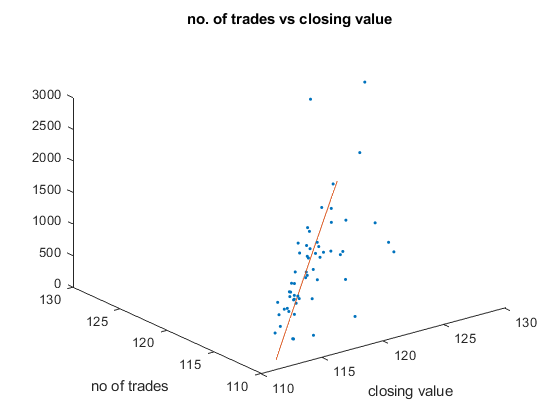

error = 561.7887

        piecewise(x,y)
        
    end
end